%https://www.electrical4u.com/magnetic-reluctance/
clear
filename = 'design_params_ref.xlsx';
[NUM,TXT,RAW] = xlsread(filename);
PI = pi;
for i=1:size(RAW,1)
    eval(RAW(i,1) + " = " + RAW(i,2))
end

rom = 0.5000

clearance = 0.0500

valve_seat_outlet_orifice_d = 0.5000

valve_seat_outlet_orifice_rad = 0.5000

valve_seat_outlet_d = 20

valve_seat_outlet_h = 3

valve_seat_outlet_face_oring_din = 0

valve_seat_outlet_face_oring_dout = 0

valve_seat_outlet_face_oring_h = 0

valve_seat_inlet_h = 3

valve_seat_upper_h = 5

valve_seat_upper_face_oring_din = 0

valve_seat_upper_face_oring_dout = 0

valve_seat_upper_face_oring_t = 0

valve_seat_upper_rad_oring_d = 0

valve_seat_upper_rad_oring_t = 0

valve_seat_h = 11

valve_seat_din = 8

valve_cone_cone_d = 4

valve_cone_cone_h = 3

valve_cone_h = 3

valve_cone_hole_d = 1

valve_cone_insert_d = 2

valve_cone_insert_h = 3

valve_spool_d = 7.9500

valve_spool_h = 17

valve_spool_insert_d = 2

valve_spool_insert_h = 3

valve_spool_hole_d = 1

valve_spool_hole_h = 13.6000

valve_spool_hole_2_d = 1

valve_spool_hole_2_h = 10.8800

coil_wire_A = 0.0500

coil_wire_d = 0.2523

coil_h = 25

coil_din = 11

coil_dout = 17

coil_former_din = 11

coil_former_dout = 17

coil_former_h_in = 25

coil_former_h_out = 28

coil_former_hole_d = 8

magnetic_bottom_dout = 17

magnetic_bottom_h = 3

magnetic_bottom_din = 8

magnetic_bottom_face_oring_din = 0

magnetic_bottom_face_oring_dout = 0

magnetic_bottom_face_oring_t = 0

magnetic_top_boss_dout = 8

magnetic_top_boss_din = 1.5000

magnetic_top_boss_h = 14

magnetic_top_h = 8

magnetic_top_dout = 19

magnetic_top_din = 4

magnetic_top_hole_d = 6

magnetic_top_hole_h = 6

magnetic_top_face_oring_din = 0

magnetic_top_face_oring_dout = 0

magnetic_top_face_oring_t = 0

shell_din = 17.0500

shell_dout = 20

shell_h = 31

spring_rod_long_h = 16.5000

spring_rod_long_d = 1.4500

spring_rod_thick_d = 5

spring_rod_thick_h = 1

spring_rod_short_h = 4.5000

spring_rod_short_d = 1.4500

fastener_dout = 24

fastener_h = 5

fastener_face_oring_din = 0

fastener_face_oring_dout = 0

fastener_face_oring_t = 0

casing_din = 19

casing_h = 55

casing_t = 3

casing_thread_h = 5

## Modification

## Sealin Surface

do = 0.5;
r = 0.25;
R = 0.5 * do + r;
fun = @(x) 2*pi*(sqrt(r^2 - x.^2) + R).*sqrt(r^2./(r^2 - x.^2))

fun = function_handle with value:
    @(x)2*pi*(sqrt(r^2-x.^2)+R).*sqrt(r^2./(r^2-x.^2))


S = integral(fun,0,r)

S = 1.6264

Ao = pi * do^2 / 4

Ao = 0.1963

Ap = pi * R^2

Ap = 0.7854

20.5*S

ans = 33.3412

50*Ap

ans = 39.2699

## Magnetic Reluctance

rel_perm = 850

rel_perm = 850

air_perm = 1.25663753*1e-6

air_perm = 1.2566e-06

perm = rel_perm * air_perm

perm = 0.0011

### Magnetic Top

magnetic_top_boss_center_cylnder_r = 0.25 * (magnetic_top_boss_dout + magnetic_top_boss_din)

magnetic_top_boss_center_cylnder_r = 2.3750

shell_center_cylinder_r = 0.25 * (shell_dout + shell_din)

shell_center_cylinder_r = 9.2625

MR_volume_magnetic_top_hor_l = (shell_center_cylinder_r - magnetic_top_boss_center_cylnder_r) * 1e-3

MR_volume_magnetic_top_hor_l = 0.0069

MR_volume_magnetic_top_hor_A =...
    (pi * (magnetic_top_boss_center_cylnder_r + shell_center_cylinder_r) * ... mean cylnder diameter
    (magnetic_top_h - magnetic_top_hole_h)) * 1e-6

MR_volume_magnetic_top_hor_A = 7.3121e-05

MR_magnetic_top_hor = MR_volume_magnetic_top_hor_l / ( perm * MR_volume_magnetic_top_hor_A )

MR_magnetic_top_hor = 8.8185e+04

MR_volume_magnetic_top_ver_l_out = 0.5 * (magnetic_top_h - magnetic_top_hole_h) * 1e-3

MR_volume_magnetic_top_ver_l_out = 1.0000e-03

MR_volume_magnetic_top_ver_A_out = 0.25 * pi * (magnetic_top_dout^2 - shell_din^2) * 1e-6

MR_volume_magnetic_top_ver_A_out = 5.5212e-05

MR_magnetic_top_ver_out = MR_volume_magnetic_top_ver_l_out / ( perm * MR_volume_magnetic_top_ver_A_out ) % mm / (H/m mm^2) -> (m mm / H mm^2) -> 1e3 / H

MR_magnetic_top_ver_out = 1.6957e+04

MR_volume_magnetic_top_ver_l_in = (MR_volume_magnetic_top_ver_l_out + magnetic_top_boss_h) * 1e-3

MR_volume_magnetic_top_ver_l_in = 0.0140

MR_volume_magnetic_top_ver_A_in = 0.25 * pi * (magnetic_top_boss_dout^2 - magnetic_top_boss_din^2) * 1e-6

MR_volume_magnetic_top_ver_A_in = 4.8498e-05

MR_magnetic_top_ver_in = MR_volume_magnetic_top_ver_l_in / ( perm * MR_volume_magnetic_top_ver_A_in ) % mm / (H/m mm^2) -> (m mm / H mm^2) -> 1e3 / H

MR_magnetic_top_ver_in = 2.7027e+05

MR_magnetic_top = (MR_magnetic_top_hor + MR_magnetic_top_ver_out + MR_magnetic_top_ver_in)

MR_magnetic_top = 3.7541e+05

mmf = (200*0.75)*MR_magnetic_top

mmf = 5.6312e+07

### Magnetic Bottom

MR_surface_magnetic_bottom_hor_l = 0.5 * (magnetic_bottom_dout - magnetic_bottom_din) * 1e-3

MR_surface_magnetic_bottom_hor_l = 0.0045

MR_surface_magnetic_bottom_hor_A = pi * 0.5 * (magnetic_bottom_dout + magnetic_bottom_din) * magnetic_bottom_h * 1e-6

MR_surface_magnetic_bottom_hor_A = 1.1781e-04

MR_magnetic_bottom = MR_surface_magnetic_bottom_hor_l / (perm * MR_surface_magnetic_bottom_hor_A)

MR_magnetic_bottom = 3.5760e+04

### Shell

MR_surface_shell_hor_l = 0.5 * (shell_dout - shell_din) * 1e-3

MR_surface_shell_hor_l = 0.0015

MR_surface_shell_hor_A = pi * 0.5 * (shell_dout + shell_din) * magnetic_bottom_h * 1e-6

MR_surface_shell_hor_A = 1.7459e-04

MR_shell_hor = MR_surface_shell_hor_l / (perm * MR_surface_shell_hor_A)

MR_shell_hor = 7.9092e+03

MR_surface_shell_ver_l = (shell_h - 0.5 * magnetic_bottom_h) * 1e-3

MR_surface_shell_ver_l = 0.0295

MR_surface_shell_ver_A = pi * 0.25 * (shell_dout^2 -shell_din^2) * 1e-6

MR_surface_shell_ver_A = 8.5842e-05

MR_shell_ver = MR_surface_shell_ver_l / (perm * MR_surface_shell_ver_A)

MR_shell_ver = 3.2173e+05

MR_shell = MR_shell_ver + MR_shell_hor

MR_shell = 3.2964e+05

### Shell - Magnetic Bottom Clearance

MR_surface_shell_mag_bot_hor_l = 0.5 * clearance * 1e-3

MR_surface_shell_mag_bot_hor_l = 2.5000e-05

MR_surface_shell_mag_bot_hor_A = pi * 0.5 * (shell_din + magnetic_bottom_dout) * magnetic_bottom_h * 1e-6

MR_surface_shell_mag_bot_hor_A = 1.6046e-04

MR_shell_mag_bot_hor = MR_surface_shell_mag_bot_hor_l / (perm * MR_surface_shell_mag_bot_hor_A)

MR_shell_mag_bot_hor = 145.8656

### Shell - Magnetic Top Clearance

MR_surface_shell_mag_top_hor_l = 0.5 * clearance * 1e-3

MR_surface_shell_mag_top_hor_l = 2.5000e-05

MR_surface_shell_mag_top_hor_A = pi * 0.5 * (shell_din + magnetic_top_dout)...
    * (magnetic_top_h - magnetic_top_hole_h) * 1e-6

MR_surface_shell_mag_top_hor_A = 1.1325e-04

MR_shell_mag_top_hor = MR_surface_shell_mag_top_hor_l / (perm * MR_surface_shell_mag_top_hor_A)

MR_shell_mag_top_hor = 206.6598

### Gap

gap = 0.3

gap = 0.3000

MR_gap_hor_l = gap * 1e-3

MR_gap_hor_l = 3.0000e-04

MR_gap_hor_A = 0.25 * pi * (valve_spool_d^2 - magnetic_top_boss_din^2) * 1e-6

MR_gap_hor_A = 4.7872e-05

MR_gap = MR_gap_hor_l / (air_perm * MR_gap_hor_A)

MR_gap = 4.9869e+06

### Valve Spool

MR_surface_valve_spool_hor_l = 0.5 * (valve_spool_d - valve_spool_hole_d) * 1e-3

MR_surface_valve_spool_hor_l = 0.0035

MR_surface_valve_spool_hor_A = pi * 0.5 * (valve_spool_d + valve_spool_hole_d) * magnetic_bottom_h * 1e-6

MR_surface_valve_spool_hor_A = 4.2176e-05

MR_valve_spool_hor = MR_surface_valve_spool_hor_l / (perm * MR_surface_valve_spool_hor_A)

MR_valve_spool_hor = 7.7137e+04

MR_surface_valve_spool_ver_l = (0.5 * shell_h - gap) * 1e-3

MR_surface_valve_spool_ver_l = 0.0152

MR_surface_valve_spool_ver_A = pi * 0.25 * (valve_spool_d^2 - valve_spool_hole_d^2) * 1e-6

MR_surface_valve_spool_ver_A = 4.8854e-05

MR_valve_spool_ver = MR_surface_valve_spool_ver_l / (perm * MR_surface_valve_spool_ver_A)

MR_valve_spool_ver = 2.9128e+05

MR_valve_spool = MR_valve_spool_ver + MR_valve_spool_hor

MR_valve_spool = 3.6842e+05

### Valve Spool - Magnetic Bottom clearance

MR_surface_valve_spool_magnetic_bottom_hor_l = 0.5 * clearance * 1e-3

MR_surface_valve_spool_magnetic_bottom_hor_l = 2.5000e-05

MR_surface_valve_spool_magnetic_bottom_hor_A = pi * 0.5 * (valve_spool_d + magnetic_bottom_din) * magnetic_bottom_h * 1e-6

MR_surface_valve_spool_magnetic_bottom_hor_A = 7.5163e-05

MR_valve_spool_magnetic_bottom_hor = MR_surface_valve_spool_magnetic_bottom_hor_l / (air_perm * MR_surface_valve_spool_magnetic_bottom_hor_A)

MR_valve_spool_magnetic_bottom_hor = 2.6468e+05

### Total

MR_total = MR_valve_spool + MR_gap + MR_shell + MR_magnetic_bottom + MR_magnetic_top +...
    MR_valve_spool_magnetic_bottom_hor + MR_shell_mag_bot_hor + MR_shell_mag_top_hor

MR_total = 6.3612e+06

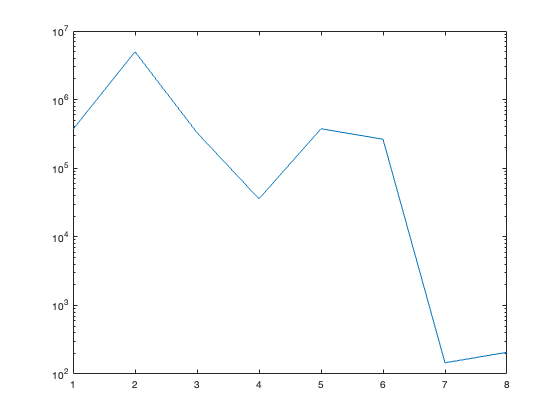

semilogy([MR_valve_spool,MR_gap,MR_shell,MR_magnetic_bottom,MR_magnetic_top,...
    MR_valve_spool_magnetic_bottom_hor,MR_shell_mag_bot_hor,MR_shell_mag_top_hor])

rec_max_A = 3.5; % A/mm2;
wire_areas = [0.05 0.1 0.2 0.4 0.7 1]; %mm^2
for i=1:length(wire_areas)
    wire_area = wire_areas(i)
    R_per_km = 18.426905*wire_area^-0.997135
    wire_d = 2 * sqrt(wire_area/pi);
    wire_curr_cap = rec_max_A * wire_area;
    coil_cross_section_A = (coil_dout - coil_din) * coil_h; % mm2;
    N = coil_cross_section_A / wire_d^2;
    wire_len = N * pi * (coil_dout + coil_din) * 1e-3;
    wire_R = wire_len * R_per_km * 1e-3;
    sol_V(i) = wire_R * wire_curr_cap;
    sol_P(i) = wire_R * wire_curr_cap^2;
    
    
    flux = N * wire_curr_cap / MR_total;
    Fmag = flux^2 / (air_perm * MR_gap_hor_A);
end

wire_area = 0.0500

R_per_km = 365.3886

wire_area = 0.1000

R_per_km = 183.0574

wire_area = 0.2000

R_per_km = 91.7107

wire_area = 0.4000

R_per_km = 45.9465

wire_area = 0.7000

R_per_km = 26.2973

wire_area = 1

R_per_km = 18.4269

Fmag

Fmag = 69.8525

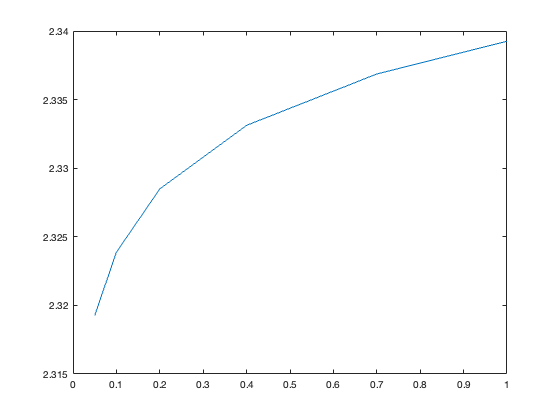

plot(wire_areas,sol_P)

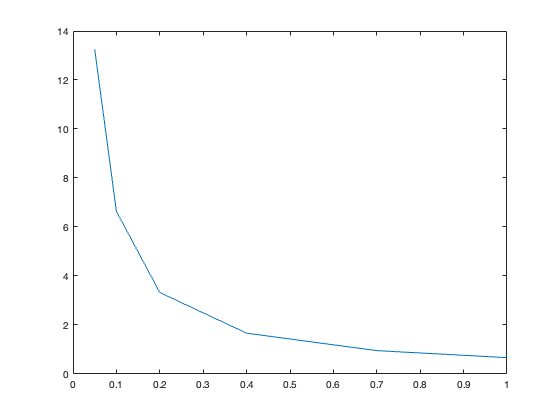

plot(wire_areas,sol_V)

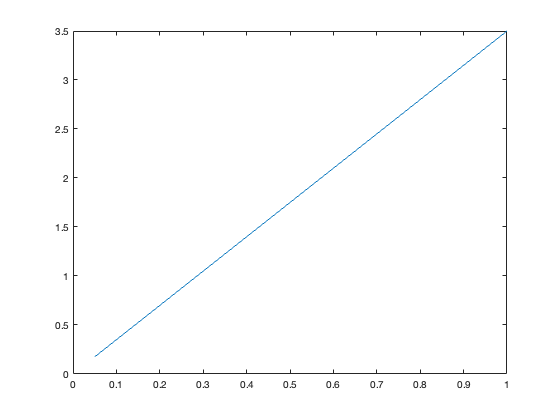

plot(wire_areas,sol_P./sol_V)